# XTD_A5: Decoding Trial Start Past Info

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

trlStrtWinDur = 3000;

## Compile Data

trInt_TstPrevPos = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstPrevPos = cell(mlb.seqLength, length(fileDirs));
trInt_TstPrevOdr = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstPrevOdr = cell(mlb.seqLength, length(fileDirs));

trInt_TstPrevPosType = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstPrevPosType = cell(mlb.seqLength, length(fileDirs));
trInt_TstPrevOdrType = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstPrevOdrType = cell(mlb.seqLength, length(fileDirs));

trInt_DecPrevPos = cell(mlb.seqLength, length(fileDirs));
trIntCON_DecPrevPos = cell(mlb.seqLength, length(fileDirs));
trInt_DecPrevOdr = cell(mlb.seqLength, length(fileDirs));
trIntCON_DecPrevOdr = cell(mlb.seqLength, length(fileDirs));

adcd_PrevPos = cell(mlb.seqLength, length(fileDirs));
adcd_PrevPosCON = cell(mlb.seqLength, length(fileDirs));
adcd_PrevOdr = cell(mlb.seqLength, length(fileDirs));
adcd_PrevOdrCON = cell(mlb.seqLength, length(fileDirs));

for ani = 1:length(fileDirs)
%     curAni_D = xtd_D(:,:,ani);
    curAni_D = xtd_HR(:,:,ani);
    curAni_TrialInfo = xtd_TrialInfo_FULL{ani};
    for pos = 3:mlb.seqLength
        % Extract Variables
        curPos_TrialInfo = xtd_TrialInfo_POS{pos,ani};
        % Extract Event Masks
        curPos_TrialMask = mask_Trial{pos,ani};
        if strcmp(alignment{1}, 'PokeIn')
            curPos_IntMask = mask_PreInt{pos,ani};
            curPos_IntMaskCON = mask_PreIntCON{pos,ani};
        else
            curPos_IntMask = mask_PstInt{pos,ani};
            curPos_IntMaskCON =  mask_PstIntCON{pos,ani};
        end
        % Create Trial Variables
        curTrl_trInt_TstPrevPos = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trIntCON_TstPrevPos = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trInt_TstPrevOdr = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trIntCON_TstPrevOdr = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trInt_TstPrevPosType = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trIntCON_TstPrevPosType = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trInt_TstPrevOdrType = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trIntCON_TstPrevOdrType = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo),2);
        curTrl_trInt_DecPrevPos = nan(2,length(curPos_TrialInfo));
        curTrl_trIntCON_DecPrevPos = nan(2,length(curPos_TrialInfo));
        curTrl_trInt_DecPrevOdr = nan(2,length(curPos_TrialInfo));
        curTrl_trIntCON_DecPrevOdr = nan(2,length(curPos_TrialInfo));
        curTrl_adcd_PrevPos = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo));
        curTrl_adcd_PrevPosCON = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo));
        curTrl_adcd_PrevOdr = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo));
        curTrl_adcd_PrevOdrCON = nan(trlStrtWinDur/mlb.dsRate,length(curPos_TrialInfo));
        % Analyze Trials
        for trl = 1:length(curPos_TrialInfo)
            curTrlNum = curPos_TrialInfo(trl).TrialNum;
            prevTrlPos = curAni_TrialInfo(curTrlNum-1).Position;
            prevTrlNormPos = mod(curAni_TrialInfo(curTrlNum-1).Odor,10);
            taoCheck = prevTrlPos ~= prevTrlNormPos;
            prevTrlPos_D = curAni_D{pos,prevTrlPos}(:,:,trl);
            prevTrlNormPos_D = curAni_D{pos,prevTrlNormPos}(:,:,trl);
            % Create a trial start window mask
            curTrlStrtNdx = find(curPos_TrialMask(:,trl),1,'first');
            replayMask = false(size(mlb.obsvTimeVect));
            replayMask(curTrlStrtNdx-(trlStrtWinDur/2/mlb.dsRate):curTrlStrtNdx+((trlStrtWinDur/2/mlb.dsRate)-1)) = true;
            % Collect Data - Interval Trained Test Previous Position/Odor
            curTrl_trInt_TstPrevPos(:,trl,taoCheck+1) = mean(prevTrlPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
            curTrl_trIntCON_TstPrevPos(:,trl,taoCheck+1) = mean(prevTrlPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
            curTrl_trInt_TstPrevOdr(:,trl,taoCheck+1) = mean(prevTrlNormPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
            curTrl_trIntCON_TstPrevOdr(:,trl,taoCheck+1) = mean(prevTrlNormPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
            % Collect Data - Interval Trained Decode Previous Position/Odor
            curTrl_trInt_DecPrevPos(taoCheck+1,trl) = mean(prevTrlPos_D(replayMask,curPos_IntMask(:,trl)),  'all', 'omitnan');
            curTrl_trIntCON_DecPrevPos(taoCheck+1,trl) = mean(prevTrlPos_D(replayMask,curPos_IntMaskCON(:,trl)), 'all', 'omitnan');
            curTrl_trInt_DecPrevOdr(taoCheck+1,trl) = mean(prevTrlNormPos_D(replayMask,curPos_IntMask(:,trl)), 'all', 'omitnan');
            curTrl_trIntCON_DecPrevOdr(taoCheck+1,trl) = mean(prevTrlNormPos_D(replayMask,curPos_IntMaskCON(:,trl)), 'all', 'omitnan');
            % Collect Data - TAO broken down by Skips/Repeats
            if taoCheck
                if prevTrlPos > prevTrlNormPos
                    curTrl_trInt_TstPrevPosType(:,trl,1) = mean(prevTrlPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_trIntCON_TstPrevPosType(:,trl,1) = mean(prevTrlPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                    curTrl_trInt_TstPrevOdrType(:,trl,1) = mean(prevTrlNormPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_trIntCON_TstPrevOdrType(:,trl,1) = mean(prevTrlNormPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                else
                    curTrl_trInt_TstPrevPosType(:,trl,2) = mean(prevTrlPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_trIntCON_TstPrevPosType(:,trl,2) = mean(prevTrlPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                    curTrl_trInt_TstPrevOdrType(:,trl,2) = mean(prevTrlNormPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_trIntCON_TstPrevOdrType(:,trl,2) = mean(prevTrlNormPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                end
                if (prevTrlPos == 2) && (prevTrlNormPos == 4)
                    curTrl_adcd_PrevPos(:,trl) = mean(prevTrlPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_adcd_PrevPosCON(:,trl) = mean(prevTrlPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                    curTrl_adcd_PrevOdr(:,trl) = mean(prevTrlNormPos_D(replayMask,curPos_IntMask(:,trl)), 2, 'omitnan');
                    curTrl_adcd_PrevOdrCON(:,trl) = mean(prevTrlNormPos_D(replayMask,curPos_IntMaskCON(:,trl)), 2, 'omitnan');
                end
            end
        end
        trInt_TstPrevPos{pos,ani} = curTrl_trInt_TstPrevPos;
        trIntCON_TstPrevPos{pos,ani} = curTrl_trIntCON_TstPrevPos;
        trInt_TstPrevOdr{pos,ani} = curTrl_trInt_TstPrevOdr;
        trIntCON_TstPrevOdr{pos,ani} = curTrl_trIntCON_TstPrevOdr;

        trInt_TstPrevPosType{pos,ani} = curTrl_trInt_TstPrevPosType;
        trIntCON_TstPrevPosType{pos,ani} = curTrl_trIntCON_TstPrevPosType;
        trInt_TstPrevOdrType{pos,ani} = curTrl_trInt_TstPrevOdrType;
        trIntCON_TstPrevOdrType{pos,ani} = curTrl_trIntCON_TstPrevOdrType;

        trInt_DecPrevPos{pos,ani} = curTrl_trInt_DecPrevPos;
        trIntCON_DecPrevPos{pos,ani} = curTrl_trIntCON_DecPrevPos;
        trInt_DecPrevOdr{pos,ani} = curTrl_trInt_DecPrevOdr;
        trIntCON_DecPrevOdr{pos,ani} = curTrl_trIntCON_DecPrevOdr;

        adcd_PrevPos{pos,ani} = curTrl_adcd_PrevPos;
        adcd_PrevPosCON{pos,ani} = curTrl_adcd_PrevPosCON;
        adcd_PrevOdr{pos,ani} = curTrl_adcd_PrevOdr;
        adcd_PrevOdrCON{pos,ani} = curTrl_adcd_PrevOdrCON;
    end
end


trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

## Plot Things

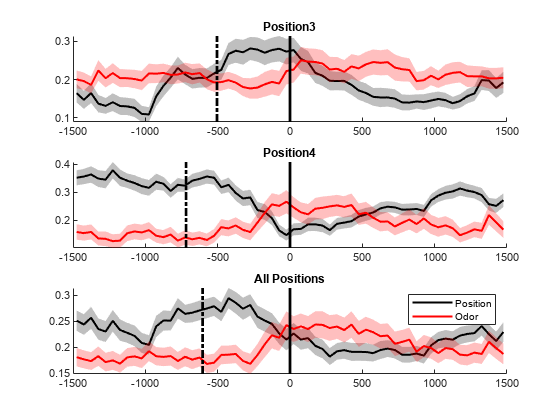

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;
% conOno = false;
conOno = true;
if conOno 
    tstPrevPos = trIntCON_TstPrevPos;
    tstPrevOdr = trIntCON_TstPrevOdr;
else
    tstPrevPos = trInt_TstPrevPos;
    tstPrevOdr = trInt_TstPrevOdr;
end
figure;
for pos = 3:mlb.seqLength
    temp_tstPrevPos = cell2mat(tstPrevPos(pos,:));
    temp_tstPrevOdr = cell2mat(tstPrevOdr(pos,:));
    subplot(mlb.seqLength-1,1,pos-2)
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,2), 2, 0, 'k');
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,2), 2, 0, 'r');        
    plot(repmat(median(cell2mat(lat_PrtLight(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    title(sprintf('Position%i',pos));
end
temp_tstPrevPos = cell2mat(tstPrevPos(:)');
temp_tstPrevOdr = cell2mat(tstPrevOdr(:)');
subplot(mlb.seqLength-1,1,mlb.seqLength-1)
p = nan(1,2);
p(1) = mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,2), 2, 0, 'k');
p(2) = mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,2), 2, 0, 'r');
plot(repmat(median(cell2mat(trialLIGHTlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
title('All Positions');
legend(p, [{'Position'}, {'Odor'}]);

## Break down by OutSeq Type

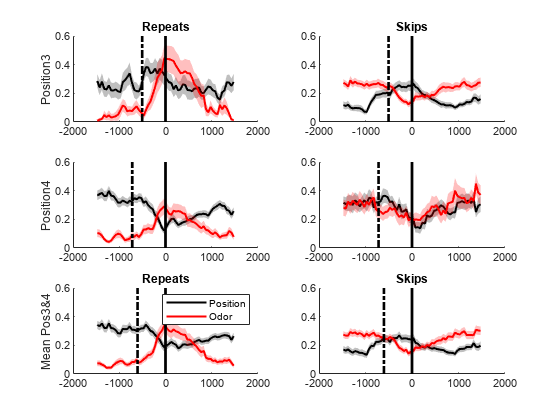

conOno = false;
conOno = true;
if conOno 
    tstPrevPos = trIntCON_TstPrevPosType;
    tstPrevOdr = trIntCON_TstPrevOdrType;
else
    tstPrevPos = trInt_TstPrevPosType;
    tstPrevOdr = trInt_TstPrevOdrType;
end
figure;
sps = nan(3,2);
for pos = 3:mlb.seqLength
    temp_tstPrevPos = cell2mat(tstPrevPos(pos,:));
    temp_tstPrevOdr = cell2mat(tstPrevOdr(pos,:));
    sps(pos,1) = subplot(mlb.seqLength-1,2,sub2ind([2,mlb.seqLength-1],1,pos-2));
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,1), 2, 0, 'k');
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,1), 2, 0, 'r');        
    set(gca,'ylim', [0 0.6]);
    plot(repmat(median(cell2mat(lat_PrtLight(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    ylabel(sprintf('Position%i',pos));
    if pos==3
        title('Repeats');
    end
    sps(pos,2) = subplot(mlb.seqLength-1,2,sub2ind([2,mlb.seqLength-1],2,pos-2));
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,2), 2, 0, 'k');
    mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,2), 2, 0, 'r');        
    set(gca,'ylim', [0 0.6]);
    plot(repmat(median(cell2mat(lat_PrtLight(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    if pos==3
        title('Skips');
    end
end
temp_tstPrevPos = cell2mat(tstPrevPos(:)');
temp_tstPrevOdr = cell2mat(tstPrevOdr(:)');
sps(mlb.seqLength-1,1) = subplot(mlb.seqLength-1,2,sub2ind([2,mlb.seqLength-1],1,mlb.seqLength-1));
p = nan(1,2);
p(1) = mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,1), 2, 0, 'k');
p(2) = mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,1), 2, 0, 'r');
set(gca,'ylim', [0 0.6]);
plot(repmat(median(cell2mat(trialLIGHTlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
title('Repeats');
ylabel('Mean Pos3&4');
legend(p, [{'Position'}, {'Odor'}]);
sps(mlb.seqLength-1,2) = subplot(mlb.seqLength-1,2,sub2ind([2,mlb.seqLength-1],2,mlb.seqLength-1));
mlb.PlotMeanVarLine(windowXticks, temp_tstPrevPos(:,:,2), 2, 0, 'k');
mlb.PlotMeanVarLine(windowXticks, temp_tstPrevOdr(:,:,2), 2, 0, 'r');
set(gca,'ylim', [0 0.6]);
plot(repmat(median(cell2mat(trialLIGHTlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)'))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
title('Skips');
linkaxes(sps,'xy');

## Look at ADCD Specifically

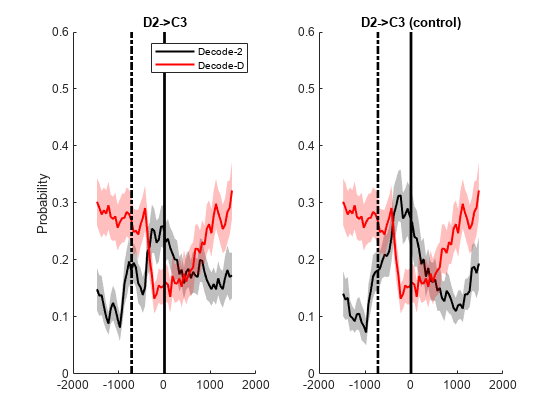

figure;
sps = nan(1,2);
sps(1) = subplot(1,2,1);
p = nan(1,2);
p(1) = mlb.PlotMeanVarLine(windowXticks, cell2mat(adcd_PrevPos(3,:)), 2, 0, 'k');
p(2) = mlb.PlotMeanVarLine(windowXticks, cell2mat(adcd_PrevOdr(3,:)), 2, 0, 'r');
set(gca,'ylim', [0 0.6]);
plot(repmat(median(cell2mat(lat_PrtLight(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(lat_TrlStart(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
legend(p, [{'Decode-2'}, {'Decode-D'}]);
ylabel('Probability');
title('D2->C3');
sps(2) = subplot(1,2,2);
mlb.PlotMeanVarLine(windowXticks, cell2mat(adcd_PrevPosCON(3,:)), 2, 0, 'k');
mlb.PlotMeanVarLine(windowXticks, cell2mat(adcd_PrevOdr(3,:)), 2, 0, 'r');
set(gca,'ylim', [0 0.6]);
plot(repmat(median(cell2mat(lat_PrtLight(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(lat_TrlStart(pos,:)))*1000, [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
title('D2->C3 (control)');
linkaxes(sps,'xy');